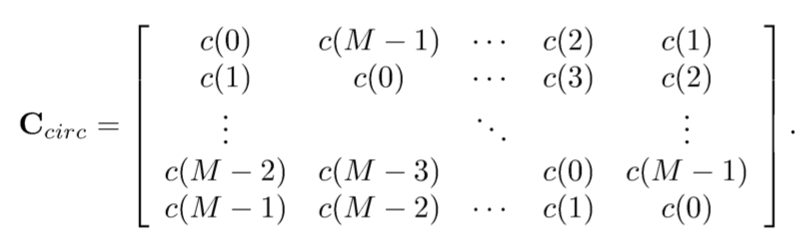

Input: Channel inpulse response vector c, and modulation symbol size M.

Output: Circulant matrix of size (M, M).

See "Filter Bank Transceivers for OFDM and DMT Systems" p.109 for details.

function C_circ = circulant_matrix(c, M)
C_circ = zeros(M);
c_pad = [c; zeros(M-length(c), 1)];
C_circ(:, 1) = c_pad;
for idx = 2:M
    C_circ(:, idx) = circshift(c_pad, idx-1);
end